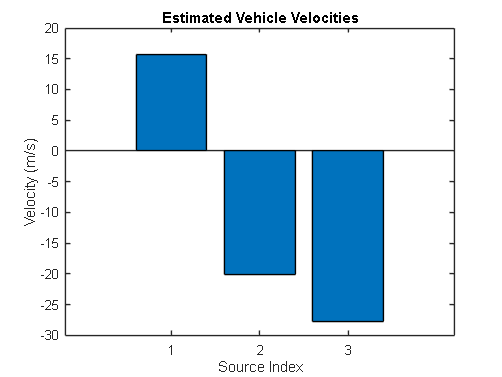

% AOA_MUSIC_V2X_STEP3.m – MUSIC-based V2X AoA & Velocity Estimation + Beamforming

% Simulation parameters
M = 8;                      % Number of antennas
K = 3;                      % Number of sources (vehicles)
d = 0.0107 / 2;             % Antenna spacing (half-wavelength)
wavelength = 0.0107;        % Wavelength at 28 GHz
SNR = 20;                   % Signal-to-noise ratio in dB
fs = 1e6;                   % Sampling frequency
N = 1024;                   % Number of snapshots

% Generate V2X signal
[x, ~, true_DoAs, doppler_shifts, speeds] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs);

% Step 1: Estimate DoAs
doa_estimates = algo(x, M, K, d, wavelength);

% Step 2: Estimate velocities from Doppler
estimated_velocities = estimate_velocity(doa_estimates, doppler_shifts, wavelength);

True DoAs (deg):
  -37.0139   33.0579   36.7651

Estimated DoAs (deg):
  -37.0000   33.0000   33.1000

Doppler shifts (Hz):
   1.0e+03 *

    1.4580   -1.8699   -2.5827

Estimated Velocities (m/s):
   15.6211  -20.0341  -27.6718



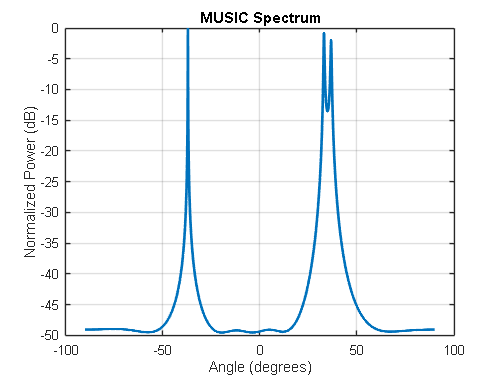

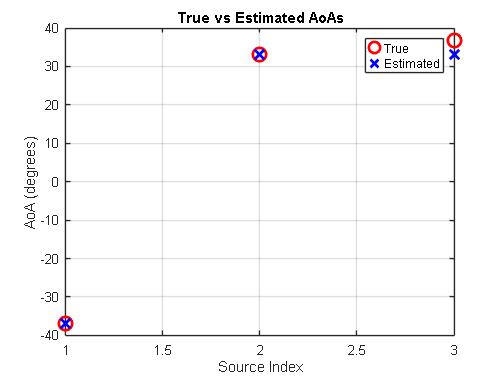


% Step 3: Apply Beamforming (Delay-and-Sum)
x_beamformed = beamform(x, doa_estimates, M, d, wavelength);

% Plot results
plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, estimated_velocities);

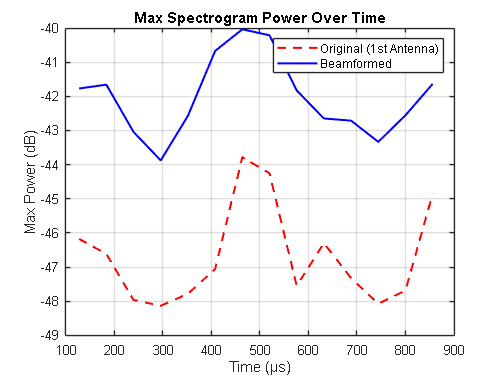


% Spectrogram before and after beamforming
% Compare Spectrogram Peak Power Levels Before and After Beamforming
window = 256;
noverlap = 200;
nfft = 512;

% Original signal from 1st antenna
[~, F, T, P1] = spectrogram(x(1,:), window, noverlap, nfft, fs);
maxP1 = max(10*log10(abs(P1)), [], 1);  % Max power over frequency at each time

% Beamformed signal
[~, ~, ~, P2] = spectrogram(x_beamformed, window, noverlap, nfft, fs);
maxP2 = max(10*log10(abs(P2)), [], 1);

% Plot comparative max power vs time
figure;
plot(T*1e6, maxP1, 'r--', 'LineWidth', 1.5); hold on;
plot(T*1e6, maxP2, 'b-', 'LineWidth', 1.5);
xlabel('Time (μs)');
ylabel('Max Power (dB)');
legend('Original (1st Antenna)', 'Beamformed');
title('Max Spectrogram Power Over Time');
grid on;



%% FUNCTIONS

function [x, A, true_DoAs, doppler_shifts, speeds] = v2x_signal_simulation(M, K, d, wavelength, SNR, N, fs)
    c = 3e8;
    fc = 28e9;
    t = (0:N-1)/fs;

    true_DoAs = sort(-60 + 120 * rand(1, K));
    speeds = -30 + 60 * rand(1, K);
    doppler_shifts = fc * speeds / c;

    theta = deg2rad(true_DoAs);
    A = exp(-1i*2*pi*d*(0:M-1).' * sin(theta)/wavelength);

    S = zeros(K, N);
    for k = 1:K
        S(k,:) = sqrt(0.5)*(randn(1,N) + 1i*randn(1,N)) .* exp(1i*2*pi*doppler_shifts(k)*t);
    end

    noise_var = 10^(-SNR/10) * trace(A*(S*S')*A') / (M*N);
    noise = sqrt(noise_var/2) * (randn(M,N) + 1i*randn(M,N));

    x = A * S + noise;
end

function doa_estimates = algo(x, M, K, d, wavelength)
    theta = -90:0.1:90;
    [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    [~, idx] = sort(Pmusic, 'descend');
    idx = idx(1:K);
    initial_DoAs = theta(idx);

    doa_estimates = zeros(1, K);
    for i = 1:K
        err = @(xval) abs(1 / abs((a(xval,d,M,wavelength)' * Vn)*(Vn' * a(xval,d,M,wavelength))) - Pmusic(idx(i)));
        doa_estimates(i) = fminsearch(err, initial_DoAs(i));
    end
end

function a_vec = a(angle, d, M, wavelength)
    a_vec = exp(-1i * 2*pi * d * (0:M-1).' * sind(angle) / wavelength);
end

function [Vn, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta)
    Rxx = (x*x') / size(x,2);
    [V,D] = eig(Rxx);
    [~,idx] = sort(diag(D), 'descend');
    V = V(:,idx);
    Vn = V(:, K+1:end);

    Pmusic = arrayfun(@(ang) 1 / abs((a(ang,d,M,wavelength)' * Vn)*(Vn' * a(ang,d,M,wavelength))), theta);
end

function estimated_velocities = estimate_velocity(doa_estimates, doppler_shifts, wavelength)
    c = 3e8;
    fc = 28e9;
    estimated_velocities = (doppler_shifts * c) / fc;

    figure;
    bar(1:length(estimated_velocities), estimated_velocities);
    xlabel('Source Index');
    ylabel('Velocity (m/s)');
    title('Estimated Vehicle Velocities');
end

function x_bf = beamform(x, doa_estimates, M, d, wavelength)
    N = size(x, 2);
    x_bf = zeros(1, N);
    for k = 1:length(doa_estimates)
        w = a(doa_estimates(k), d, M, wavelength);  % Beamformer weights
        w = w / norm(w);                            % Normalize
        x_bf = x_bf + (w' * x);                     % Delay-and-Sum
    end
    x_bf = x_bf / length(doa_estimates);            % Average across sources
end


function plot_results(x, doa_estimates, M, K, d, wavelength, true_DoAs, doppler_shifts, est_vel)
    theta = -90:0.1:90;
    [~, Pmusic] = compute_music_spectrum(x, M, K, d, wavelength, theta);

    disp('True DoAs (deg):'); disp(true_DoAs);
    disp('Estimated DoAs (deg):'); disp(doa_estimates);
    disp('Doppler shifts (Hz):'); disp(doppler_shifts);
    disp('Estimated Velocities (m/s):'); disp(est_vel);

    figure;
    plot(theta, 10*log10(abs(Pmusic)/max(abs(Pmusic))), 'LineWidth', 2);
    xlabel('Angle (degrees)');
    ylabel('Normalized Power (dB)');
    title('MUSIC Spectrum');
    grid on;

    figure;
    plot(1:K, sort(true_DoAs), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
    hold on;
    plot(1:K, sort(doa_estimates), 'bx', 'LineWidth', 2, 'MarkerSize', 10);
    xlabel('Source Index');
    ylabel('AoA (degrees)');
    title('True vs Estimated AoAs');
    legend('True', 'Estimated');
    grid on;
end
